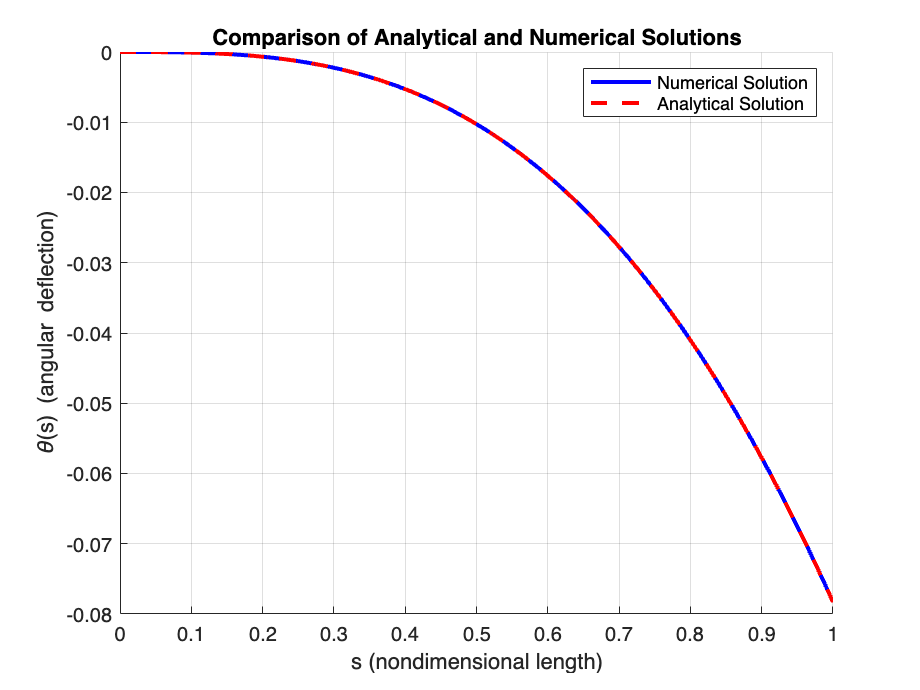

% Parameters
l_gc = 1.2;  % Dimensionless parameter
phi = pi / 6;  % Contact angle (in radians)
h = 0.5;  % Nondimensional liquid height
L = 1;  % Strip length

% Define the system of ODEs for numerical solution
ode = @(s, y) [
    y(2);  % y1' = y2
    y(3);  % y2' = y3
    -l_gc^2 * y(2) * cos(phi) - h  % y3' = -l_gc^2 * y2 * cos(phi) - h
];

% Initial conditions at s = 0 (clamped end)
y0 = [0; 0; 0];  % y1(0) = 0, y2(0) = 0, y3(0) = 0

% Solve the system of ODEs (numerical solution)
[s, y] = ode45(ode, [0 L], y0);

% Define the analytical solution (simplified case)
syms s1 C1 C2 C3 theta(s1)
eq = diff(theta, s1, 3) + l_gc^2 * diff(theta, s1) * cos(phi) + h == 0;
theta_analytical = dsolve(eq);

% Apply boundary conditions (symbolically for analytical solution)
bc1 = subs(theta_analytical, s1, 0) == 0; % θ(0) = 0
bc2 = subs(diff(theta_analytical, s1), s1, 0) == 0; % θ'(0) = 0
bc3 = subs(diff(theta_analytical, s1, 2), s1, 0) == 0; % θ''(0) = 0
constants = solve([bc1, bc2, bc3], [C1, C2, C3]);
theta_analytical = subs(theta_analytical, constants);

% Plot the comparison of numerical and analytical solutions
figure;
hold on;
plot(s, y(:,1), 'b-', 'LineWidth', 2);  % Numerical solution
fplot(theta_analytical, [0, L], 'r--', 'LineWidth', 2);  % Analytical solution
xlabel('s (nondimensional length)');
ylabel('\theta(s) (angular deflection)');
title('Comparison of Analytical and Numerical Solutions');
legend('Numerical Solution', 'Analytical Solution');
grid on;